## Initialize

clear all;

addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

area_metric = 3;


## Load & Format Macaque Data

load('./completeData/monkey_data')

% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_monkey=1:3; EVCcolor=[0.1 0.6 1];
V4rois_monkey=4:5; V4color=[1 0.2 1];
ventralrois_monkey=6:10; ventralcolor=[1 0.2 0.2];
dorsalrois_monkey=11:12; dorsalcolor=[1 .8 0];
lateralrois_monkey=13:16; lateralcolor=[0 1 0];
parietalrois_monkey=17:21; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
region_rois_monkey = {EVCrois_monkey;V4rois_monkey;ventralrois_monkey;dorsalrois_monkey;parietalrois_monkey;lateralrois_monkey};
colorscale_monkey_all=[repmat(EVCcolor,length(EVCrois_monkey),1);...
    repmat(V4color,length(V4rois_monkey),1);...
    repmat(ventralcolor,length(ventralrois_monkey),1);...
    repmat(dorsalcolor,length(dorsalrois_monkey),1);...
    repmat(lateralcolor,length(lateralrois_monkey),1);...
    repmat(parietalcolor,length(parietalrois_monkey),1)];

colorscale_monkey_all_inv = flipud(colorscale_monkey_all);
colorscale_region_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
colorscale_unique_monkey = unique(colorscale_region_monkey,'stable','rows');
colorscale_region_monkey_inv = flipud(colorscale_region_monkey);

% rename areas to match human code
for i = 1:2
    surfacearea_smoothwm{i} = monkey_data.surfacearea_smoothwm{i};
    surfacearea_pial{i} = monkey_data.surfacearea_pial{i};
end

% actual full brain surface area
total_area_cat_monkey = [monkey_data.total_size(:,1)' monkey_data.total_size(:,2)'];
total_area_sum_monkey = monkey_data.total_size(:,1)' + monkey_data.total_size(:,2)';

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_monkey = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis_monkey=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_monkey = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_monkey = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis_monkey=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_monkey = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis_monkey = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_monkey = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_monkey = surfacearea_avg;
end

% restructure data for concatenated hemis
V1_bothhemis_combined = surfacearea_catbothhemis_monkey(1,:) + surfacearea_catbothhemis_monkey(2,:);
V2_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(9:10,:),1);

cat_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_catbothhemis_monkey(11:end,:)];

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis_monkey(1,:) + surfacearea_bothhemis_monkey(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_monkey(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_monkey(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_bothhemis_monkey(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_bothhemis_monkey(9:10,:),1);

sum_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_bothhemis_monkey(11:end,:)];

% average over broad areas for raw surface area measurements
V4_combined_monkey = mean(sum_monkey(4:5,:),1);
ventral_combined_monkey = mean(sum_monkey(ventralrois_monkey-5,:),1);
dorsal_combined_monkey = mean(sum_monkey(dorsalrois_monkey-5,:),1);
lateral_combined_monkey = mean(sum_monkey(lateralrois_monkey-5,:),1);
parietal_combined_monkey = mean(sum_monkey(parietalrois_monkey-5,:),1);

region_monkey = [sum_monkey(1:3,:);V4_combined_monkey;ventral_combined_monkey;...
    dorsal_combined_monkey;lateral_combined_monkey;parietal_combined_monkey];

%combined hemis V1
normv1_monkey = sum_monkey./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normV4_combined_monkey = mean(normv1_monkey(4:5,:),1);
normventral_combined_monkey = mean(normv1_monkey(ventralrois_monkey-5,:),1);
normdorsal_combined_monkey = mean(normv1_monkey(dorsalrois_monkey-5,:),1);
normlateral_combined_monkey = mean(normv1_monkey(lateralrois_monkey-5,:),1);
normparietal_combined_monkey = mean(normv1_monkey(parietalrois_monkey-5,:),1);

region_monkey_normv1 = [normv1_monkey(1:3,:);normV4_combined_monkey;normventral_combined_monkey;...
    normdorsal_combined_monkey;normlateral_combined_monkey;normparietal_combined_monkey];

alllabels_monkey = cat(2,{'V1','V2','V3','V4','V4A'},monkey_data.labels(11:end));
alllabels_monkey_region = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};

human_blue = [0 0.4470 0.7410];
monkey_orange = [0.8500 0.3250 0.0980];

## Load & Format Adult Human Data

load('./completeData/human_data')

disp(human_data.labels)

  Columns 1 through 13

    {'V1v'}    {'V1d'}    {'V2v'}    {'V2d'}    {'V3v'}    {'V3d'}    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'V3A'}    {'V3B'}

  Columns 14 through 24

    {'LO1'}    {'LO2'}    {'TO1'}    {'TO2'}    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}




% these numbers correspond to regional grouping of brain areas in plots
EVCrois_human=1:3; EVCcolor=[0 0 0.7];
V4rois_human=4; V4color=[0.6 0 0.6];
ventralrois_human=5:8; ventralcolor=[0.6 0.1 0.1];
dorsalrois_human=9:10; dorsalcolor=[0.8 .5 0];
lateralrois_human=11:14; lateralcolor=[0.2784    0.5216    0.1451];
parietalrois_human=15:21; parietalcolor=[0 0.7 0.7];

% concatenate all human area ROIs, labels, and colors
region_rois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human};
colorscale_human_all=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1)];

colorscale_human_all_inv = flipud(colorscale_human_all);
colorscale_region_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
colorscale_unique_human = unique(colorscale_region_human,'stable','rows');
colorscale_region_human_inv = flipud(colorscale_region_human);

% actual full brain surface area
total_area_cat_human = [human_data.total_size(:,1)' human_data.total_size(:,2)'];
total_area_sum_human = human_data.total_size(:,1)' + human_data.total_size(:,2)';

for i = 1:2
    surfacearea_smoothwm{i} = human_data.surfacearea_smoothwm{i};
    surfacearea_pial{i} = human_data.surfacearea_pial{i};
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm, human_data.surfacearea_pial,'UniformOutput',false);

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_human = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis_human=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_human = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_human = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis_human=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_human = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis_human = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_human = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_human = surfacearea_avg;
end

% restructure data for concatenated hemis
V1_bothhemis_combined = surfacearea_catbothhemis_human(1,:) + surfacearea_catbothhemis_human(2,:);
V2_bothhemis_combined = sum(surfacearea_catbothhemis_human(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_catbothhemis_human(5:6,:),1);
V4_bothhemis_combined = surfacearea_catbothhemis_human(7,:);

cat_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_catbothhemis_human(8:end,:)];

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis_human(1,:) + surfacearea_bothhemis_human(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_human(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_human(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis_human(7,:);

sum_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis_human(8:end,:)];

% average over broad areas for raw surface area measurements
ventral_combined_human = mean(sum_human(ventralrois_human,:),1);
dorsal_combined_human = mean(sum_human(dorsalrois_human,:),1);
lateral_combined_human = mean(sum_human(lateralrois_human,:),1);
parietal_combined_human = mean(sum_human(parietalrois_human,:),1);

region_human = [sum_human(1:4,:);ventral_combined_human;dorsal_combined_human;...
    lateral_combined_human;parietal_combined_human];

%combined hemis V1
normv1_human = sum_human./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normventral_combined_human = mean(normv1_human(ventralrois_human,:),1);
normdorsal_combined_human = mean(normv1_human(dorsalrois_human,:),1);
normlateral_combined_human = mean(normv1_human(lateralrois_human,:),1);
normparietal_combined_human = mean(normv1_human(parietalrois_human,:),1);

region_human_normv1 = [normv1_human(1:4,:);normventral_combined_human;normdorsal_combined_human;...
    normlateral_combined_human;normparietal_combined_human];

alllabels_human = cat(2,{'V1','V2','V3'},human_data.labels(7:end));
alllabels_humans_region = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};
alllabels_combined = {'EVC','V4','Ventral','Dorsal','Lateral','Parietal'};

## Supp Fig 2: Single area comparisons of macaque and human surface areas

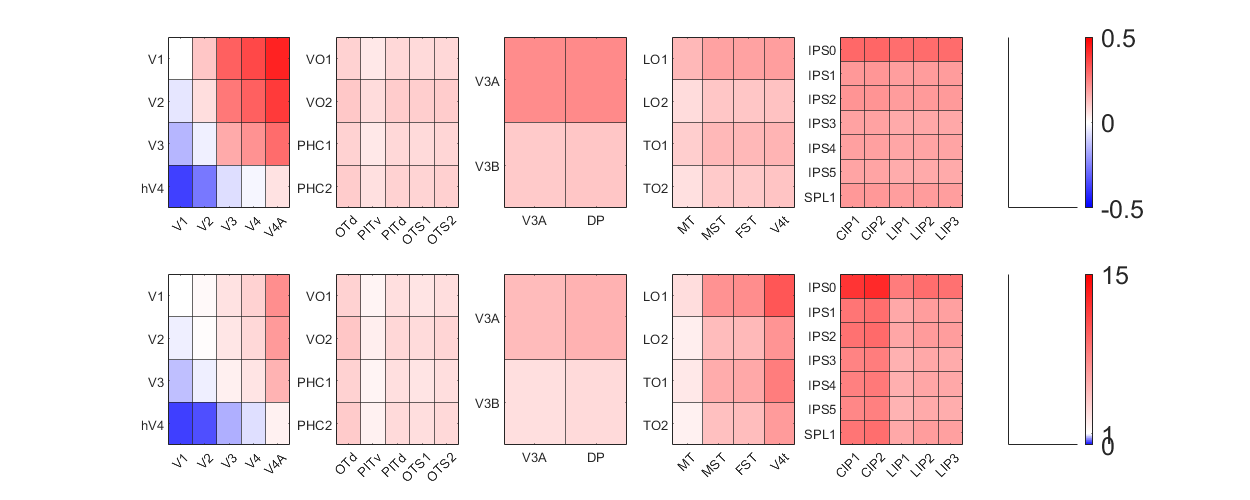

VCrois_human = {'V1','V2','V3','hV4'};
VCrois_monkey = {'V1','V2','V3','V4','V4A'};

nhuman = length(VCrois_human);
nmonkey = length(VCrois_monkey);

% calculate differences and ratios of all V1-normalized areas in EVC 
% between humans and macaques
roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(hh,:),'omitnan');
        avgmonkey = mean(normv1_monkey(mm,:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = VCrois_human;
xvalues = VCrois_monkey;

% set up colorbar for ratios
N = 17; % new CT length
x = [0 256]/256;
CT0 = [0 0 1;1 1 1];
xf = linspace(0,1,N);
bluemap = interp1(x,CT0,xf,'linear','extrap');

N = 256-17; % new CT length
x = [0 256]/256;
CT0 = [1 1 1; 1 0 0];
xf = linspace(0,1,N);
CT = interp1(x,CT0,xf,'linear','extrap');
newmap = [bluemap;CT];

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
ax1 = subplot(2,6,1);
h = imagesc(roi_diff);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
c1 = colormap(ax1,redblue);caxis([-1 1]);
% cbh1.Ticks = [-1 0 1];cbh1.FontSize = 15;
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')
% title('Human - Monkey')

ax6 = subplot(2,6,7);
h = imagesc(roi_div);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
c2 = colormap(ax6,newmap);caxis([0 15]);
% cbh.Ticks = [0 1 15];cbh.FontSize = 15;
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')
% title('Human / Monkey')

% calculate differences and ratios of all V1-normalized areas in 
% ventral visual cortex between humans and macaques
nhuman = length(ventralrois_human);
nmonkey = length(ventralrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(ventralrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(ventralrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human(ventralrois_human);
xvalues = alllabels_monkey(ventralrois_monkey);

% figure('Renderer', 'painters', 'Position', [10 10 400 1000]);
ax2 = subplot(2,6,2);
h = imagesc(roi_diff);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
colormap(ax2,redblue);caxis([-0.5 0.5]);
% cbh.Ticks = [-0.5 0 0.5];cbh.FontSize = 15;
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')
% title('Human - Monkey')

ax7 = subplot(2,6,8);
h = imagesc(roi_div);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
colormap(ax7,newmap);caxis([0 15]);
% cbh.Ticks = [0 1 15];cbh.FontSize = 15;
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')

% calculate differences and ratios of all V1-normalized areas in 
% dorsal visual cortex between humans and macaques
nhuman = length(dorsalrois_human);
nmonkey = length(dorsalrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(dorsalrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(dorsalrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human(dorsalrois_human(1:2));
xvalues = alllabels_monkey(dorsalrois_monkey);

% figure('Renderer', 'painters', 'Position', [10 10 400 1000]);
ax3 = subplot(2,6,3);
h = imagesc(roi_diff);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
colormap(ax3,redblue);caxis([-0.5 0.5]);
% cbh.Ticks = [-0.5 0 0.5];cbh.FontSize = 15;
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')

ax8 = subplot(2,6,9);
h = imagesc(roi_div);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
colormap(ax8,newmap);caxis([0 15]);
% cbh.Ticks = [0 1 15];cbh.FontSize = 15;
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')

% calculate differences and ratios of all V1-normalized areas in 
% lateral visual cortex between humans and macaques
nhuman = length(lateralrois_human);
nmonkey = length(lateralrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(lateralrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(lateralrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human(lateralrois_human);
xvalues = alllabels_monkey(lateralrois_monkey);

% figure('Renderer', 'painters', 'Position', [10 10 400 1000]);
ax4 = subplot(2,6,4);
h = imagesc(roi_diff);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
colormap(ax4,redblue);caxis([-0.5 0.5]);
% cbh.Ticks = [-0.5 0 0.5];cbh.FontSize = 15;
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')

ax9 = subplot(2,6,10);
h = imagesc(roi_div);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
colormap(ax9,newmap);caxis([0 15]);
% cbh.Ticks = [0 1 15];cbh.FontSize = 15;
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')

% calculate differences and ratios of all V1-normalized areas in 
% parietal visual cortex between humans and macaques
nhuman = length(parietalrois_human);
nmonkey = length(parietalrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(parietalrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(parietalrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human(parietalrois_human);
xvalues = alllabels_monkey(parietalrois_monkey);

% figure('Renderer', 'painters', 'Position', [10 10 400 1000]);
ax5 = subplot(2,6,5);
h = imagesc(roi_diff);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
colormap(ax5,redblue);caxis([-0.5 0.5]);
% cbh.Ticks = [-0.5 0 0.5];cbh.FontSize = 15;
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')

ax10 = subplot(2,6,11);
h = imagesc(roi_div);
xline(1.5:1:length(xvalues)-0.5)
yline(1.5:1:length(yvalues)-0.5)
xticks(1:length(xvalues))
xticklabels(xvalues)
yticks(1:length(yvalues))
yticklabels(yvalues)
colormap(ax10,newmap);caxis([0 15]);
% cbh.Ticks = [0 1 15];cbh.FontSize = 15;

% extra subplots for colorbar. when added to other subplot, it shrunk the
% size of the box so added separately
ax5 = subplot(2,6,6);
xticks([])
xticklabels([])
yticks([])
yticklabels([])
colormap(ax5,redblue);cbh = colorbar;caxis([-0.5 0.5]);
cbh.Ticks = [-0.5 0 0.5];cbh.FontSize = 15;

ax10 = subplot(2,6,12);
xticks([])
xticklabels([])
yticks([])
yticklabels([])
colormap(ax10,newmap);cbh = colorbar;caxis([0 15]);
cbh.Ticks = [0 1 15];cbh.FontSize = 15;

## Supp Fig 3: Regional expansion of visual cortex with cortical distance

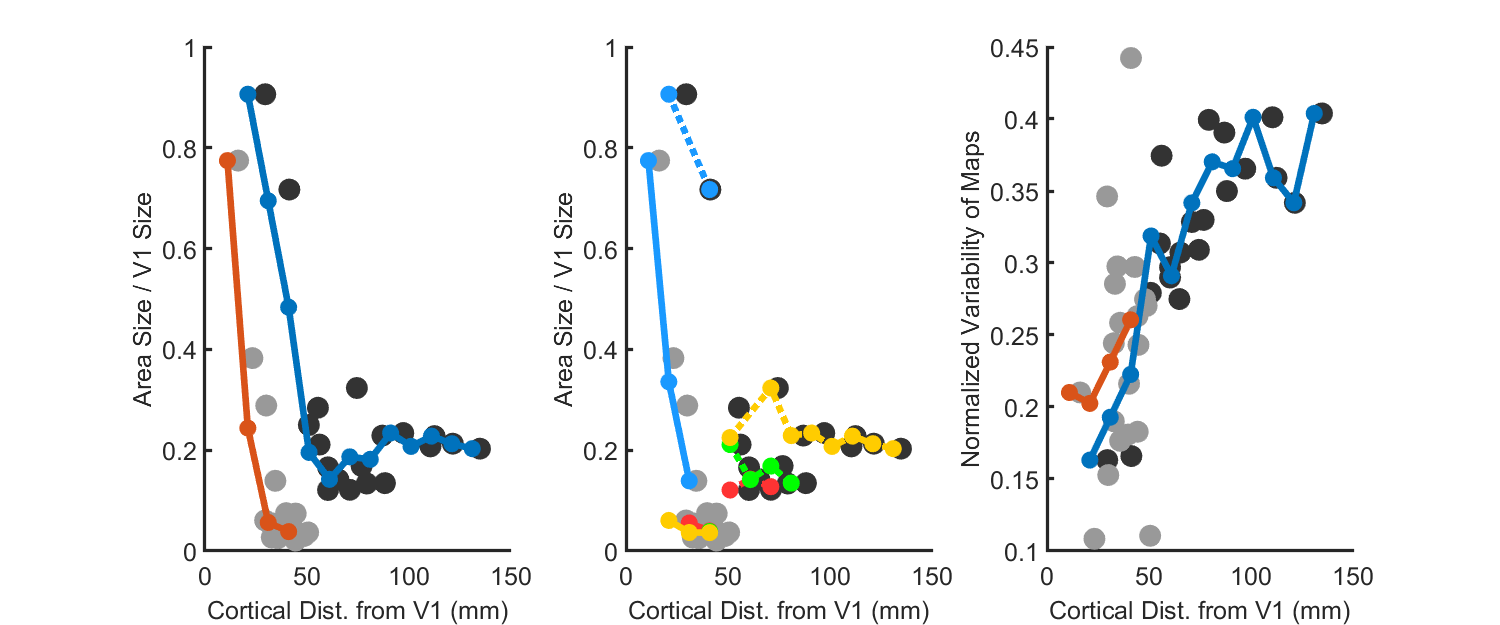

% average normalized size across subjects
humans_allareas = mean(normv1_human,2,'omitnan');
monks_allareas = mean(normv1_monkey,2,'omitnan');

% sum across ventral & dorsal components for EVC
meanmonks_cortdist_rh=nanmean(monkey_data.dist_from_v1_rh,2);
meanmonks_cortdist_lh=nanmean(monkey_data.dist_from_v1_lh,2);

meanmonks_cortdist_rh1234=[];
meanmonks_cortdist_rh1234(1)=[meanmonks_cortdist_rh(1)+meanmonks_cortdist_rh(2)];
meanmonks_cortdist_rh1234(2)=[meanmonks_cortdist_rh(3)+meanmonks_cortdist_rh(4)]/2;
meanmonks_cortdist_rh1234(3)=[meanmonks_cortdist_rh(5)+meanmonks_cortdist_rh(6)]/2;
meanmonks_cortdist_rh1234(4)=[meanmonks_cortdist_rh(7)+meanmonks_cortdist_rh(8)]/2;
meanmonks_cortdist_rh1234(5)=[meanmonks_cortdist_rh(9)+meanmonks_cortdist_rh(10)]/2;
meanmonks_cortdist_rh1234=[meanmonks_cortdist_rh1234,meanmonks_cortdist_rh(11:end)'];

meanmonks_cortdist_lh1234=[];
meanmonks_cortdist_lh1234(1)=[meanmonks_cortdist_lh(1)+meanmonks_cortdist_lh(2)];
meanmonks_cortdist_lh1234(2)=[meanmonks_cortdist_lh(3)+meanmonks_cortdist_lh(4)]/2;
meanmonks_cortdist_lh1234(3)=[meanmonks_cortdist_lh(5)+meanmonks_cortdist_lh(6)]/2;
meanmonks_cortdist_lh1234(4)=[meanmonks_cortdist_lh(7)+meanmonks_cortdist_lh(8)]/2;
meanmonks_cortdist_lh1234(5)=[meanmonks_cortdist_lh(9)+meanmonks_cortdist_lh(10)]/2;
meanmonks_cortdist_lh1234=[meanmonks_cortdist_lh1234,meanmonks_cortdist_lh(11:end)'];

% average across hemispheres
meanmonks_cortdist1234=[meanmonks_cortdist_rh1234+meanmonks_cortdist_lh1234]/2;

% average distance from V1 across subjects
meanhumans_cortdist_rh = mean(human_data.dist_from_v1_rh,2,'omitnan');
meanhumans_cortdist_lh = mean(human_data.dist_from_v1_lh,2,'omitnan');

% sum across ventral & dorsal components for EVC
meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=0;
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=0;
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];

% average across hemispheres
meanhumans_cortdist1234=[meanhumans_cortdist_rh1234+meanhumans_cortdist_lh1234]/2;

% determine distance bins for average map sizes and average correlations for
% each bin
stepsize=10;
maxrange=150;
human_meancortdist=nan(length(1:stepsize:maxrange),1);
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 150
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(4)=[human_meancortdist(3)+human_meancortdist(5)]/2;

% plot individual and average normalized map sizes based on cortical
% distance from V1
figure('Renderer', 'painters', 'Position', [10 10 1200 500])
subplot(1,3,1) 
hold on
plot(meanhumans_cortdist1234(2:end),humans_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(meanmonks_cortdist1234(2:end),monks_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(1:stepsize:maxrange,human_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(1:stepsize:maxrange,monk_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
ax.LineWidth = 2;
xlim([0 150])
xticks(0:50:150)
% xlim([0.5 max([meanmonks_cortdist1234,meanhumans_cortdist1234])+.5])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Area Size / V1 Size','fontsize',15)


% Define human and monkey data too
human_all = sum_human;
monkey_all = sum_monkey;

% Set up indices combining dorsal & parietal regions
human_evc_idx = [1, 2, 3];
human_dorsal_idx =  [9, 10, 15:21];
human_lateral_idx = [11:14];
human_ventral_idx = [5:8];

monkey_evc_idx = [1, 2, 3, 4, 5];
monkey_dorsal_idx =  [11, 12, 17:21];
monkey_lateral_idx = [13:16];
monkey_ventral_idx = [6:10];

% group V1-normalized areas into regions and average
human_evc = human_all(human_evc_idx,:); human_evc = human_evc./human_evc(1,:); human_evc = mean(human_evc,2,'omitnan');
human_dorsal = human_all(human_dorsal_idx,:); human_dorsal = human_dorsal./human_all(1,:); human_dorsal = mean(human_dorsal,2,'omitnan');
human_lateral = human_all(human_lateral_idx,:); human_lateral = human_lateral./human_all(1,:); human_lateral = mean(human_lateral,2,'omitnan');
human_ventral = human_all(human_ventral_idx,:); human_ventral = human_ventral./human_all(1,:); human_ventral = mean(human_ventral,2,'omitnan');
human_allareas = {human_evc,human_ventral,human_lateral,human_dorsal};
human_cortdist = {[meanhumans_cortdist1234(human_evc_idx)],...
                  [meanhumans_cortdist1234(human_ventral_idx)],...
                  [meanhumans_cortdist1234(human_lateral_idx)],...
                  [meanhumans_cortdist1234(human_dorsal_idx)]};

monkey_evc = monkey_all(monkey_evc_idx,:); monkey_evc = monkey_evc./monkey_evc(1,:); monkey_evc = mean(monkey_evc,2,'omitnan');
monkey_dorsal = monkey_all(monkey_dorsal_idx,:); monkey_dorsal = monkey_dorsal./monkey_all(1,:); monkey_dorsal = mean(monkey_dorsal,2,'omitnan');
monkey_lateral = monkey_all(monkey_lateral_idx,:); monkey_lateral = monkey_lateral./monkey_all(1,:); monkey_lateral = mean(monkey_lateral,2,'omitnan');
monkey_ventral = monkey_all(monkey_ventral_idx,:); monkey_ventral = monkey_ventral./monkey_all(1,:); monkey_ventral = mean(monkey_ventral,2,'omitnan');
monks_allareas = {monkey_evc,monkey_ventral,monkey_lateral,monkey_dorsal};
monkey_cortdist = {[meanmonks_cortdist1234(monkey_evc_idx)],...
                  [meanmonks_cortdist1234(monkey_ventral_idx)],...
                  [meanmonks_cortdist1234(monkey_lateral_idx)],...
                  [meanmonks_cortdist1234(monkey_dorsal_idx)]};

% determine distance bins for average map sizes in each bin
stepsize=10;
maxrange=150;
human_meancortdist = {};
monk_meancortdist = {};
for i = 1:4
    human_meancortdist{i}=nan(length(1:stepsize:maxrange),1);
    monk_meancortdist{i}=nan(length(1:stepsize:maxrange),1);
    count = 0;
    for x = 1:stepsize:maxrange
        count = count+1;
        if x < 150
            if sum([monkey_cortdist{i}>=x & monkey_cortdist{i}<(x+stepsize)]) > 1
                monk_meancortdist{i}(count)=nanmean(monks_allareas{i}([monkey_cortdist{i}>=x & monkey_cortdist{i}<x+stepsize]));
            elseif sum([monkey_cortdist{i}>=x & monkey_cortdist{i}<(x+stepsize)])
                monk_meancortdist{i}(count)=monks_allareas{i}([monkey_cortdist{i}>=x & monkey_cortdist{i}<(x+stepsize)]);
            end
            if sum([human_cortdist{i}>=x & human_cortdist{i}<(x+stepsize)]) > 1
                human_meancortdist{i}(count)=nanmean(human_allareas{i}([human_cortdist{i}>=x & human_cortdist{i}<(x+stepsize)]));
            elseif sum([human_cortdist{i}>=x & human_cortdist{i}<(x+stepsize)])
                human_meancortdist{i}(count)=human_allareas{i}([human_cortdist{i}>=x & human_cortdist{i}<(x+stepsize)]);
            end
        end
    end
end

EVCcolor=[0.1 0.6 1];
ventralcolor=[1 0.2 0.2];
dorsalcolor=[1 .8 0];
lateralcolor=[0 1 0];
monkey_colors = [EVCcolor;ventralcolor;lateralcolor;dorsalcolor];

xvals = 1:stepsize:maxrange;

% plot normalized expansion across cortical distance grouped by region
subplot(1,3,2) 
hold on
for i = 1:4
    if i==1
        plot(human_cortdist{i}(2:end),human_allareas{i}(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
        plot(monkey_cortdist{i}(2:end),monks_allareas{i}(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
    else
        plot(human_cortdist{i},human_allareas{i},'.','color',[.2 .2 .2],'MarkerSize',45)
        plot(monkey_cortdist{i},monks_allareas{i},'.','color',[.6 .6 .6],'MarkerSize',45)
    end
end
for i = 1:4
    omitnan = find(~isnan(human_meancortdist{i}));
    plot(xvals(omitnan),human_meancortdist{i}(omitnan),'.:','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
    plot(xvals,monk_meancortdist{i},'.-','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
end
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
ax.LineWidth = 2;
% xlim([0.5 max([meanmonks_cortdist1234,meanhumans_cortdist1234])+.5])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Area Size / V1 Size','fontsize',15)
res_fun = @(x) std(x,'omitnan')/mean(x,'omitnan');

% calculating variability in terms of std/mean for each area
for i = 1:size(sum_human,1)
    norm_std_human(i) = std(sum_human(i,:),'omitnan')/mean(sum_human(i,:),'omitnan');
end

for i = 1:size(sum_monkey,1)
    norm_std_monkey(i) = std(sum_monkey(i,:),'omitnan')/mean(sum_monkey(i,:),'omitnan');
end

% determine distance bins for average map variability for each bin
stepsize=10;
maxrange=150;
human_meancortdist=nan(length(1:stepsize:maxrange),1);
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 150
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(norm_std_monkey([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=norm_std_monkey([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(norm_std_human([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=norm_std_human([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(4)=[human_meancortdist(3)+human_meancortdist(5)]/2;

subplot(1,3,3); hold on;
plot(meanhumans_cortdist1234(2:end),norm_std_human(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(meanmonks_cortdist1234(2:end),norm_std_monkey(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(1:stepsize:maxrange,human_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(1:stepsize:maxrange,monk_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
ax.LineWidth = 2;
xlim([0 150])
xticks(0:50:150)
% xlim([0.5 max([meanmonks_cortdist1234,meanhumans_cortdist1234])+.5])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Normalized Variability of Maps','fontsize',15)

## Supp Fig 4A

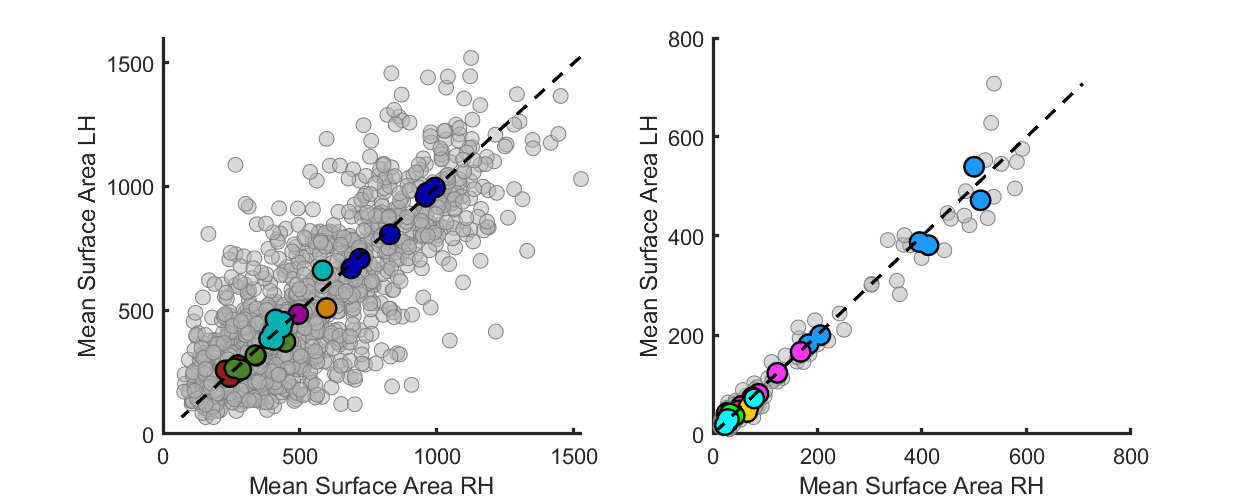

% plotting ventral and dorsal components of EVC separately so redefining
% region indices
EVCrois_human=1:6; 
V4rois_human=7; 
ventralrois_human=8:11; 
dorsalrois_human=12:13; 
lateralrois_human=14:17;
parietalrois_human=18:24;

EVCrois_monkey=1:6;
V4rois_monkey=7:10;
ventralrois_monkey=11:15;
dorsalrois_monkey=16:17; 
lateralrois_monkey=18:21;
parietalrois_monkey=22:26;

region_rois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human};
region_rois_monkey = {EVCrois_monkey;V4rois_monkey;ventralrois_monkey;dorsalrois_monkey;parietalrois_monkey;lateralrois_monkey};

% plotting area sizes across hemispheres with colored points showing area
% average
figure('Renderer', 'painters', 'Position', [10 10 1000 400])
subplot(1,2,1)
scatter(surfacearea_human{1}(:),surfacearea_human{2}(:),80,'filled','MarkerFaceColor',[0.7 0.7 0.7],'MarkerFaceAlpha',0.5,'MarkerEdgeColor',[0.5 0.5 0.5]);
hold on
for rr = 1:length(region_rois_human)
    plot(nanmean(surfacearea_human{1}(region_rois_human{rr},:),2),nanmean(surfacearea_human{2}(region_rois_human{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_human{1}(region_rois_human{rr},:),2),nanmean(surfacearea_human{2}(region_rois_human{rr},:),2),'.','Color',colorscale_unique_human(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_human{1}(:)),max(surfacearea_human{2}(:))]);
min_value=floor([min(surfacearea_human{1}(:)),min(surfacearea_human{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
xticks(0:500:2000)
yticks(0:500:2000)
set(gca,'FontSize',13)
set(gca,'linewidth',2)
% set(gca,'XTick',[])
% set(gca,'YTick',[])
% title('Human Cross-Hemisphere Surface Area Correlation')

subplot(1,2,2)
scatter(surfacearea_monkey{1}(:),surfacearea_monkey{2}(:),80,'filled','MarkerFaceColor',[0.7 0.7 0.7],'MarkerFaceAlpha',0.5,'MarkerEdgeColor',[0.5 0.5 0.5]);
hold on
for rr = 1:length(region_rois_monkey)
    plot(nanmean(surfacearea_monkey{1}(region_rois_monkey{rr},:),2),nanmean(surfacearea_monkey{2}(region_rois_monkey{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_monkey{1}(region_rois_monkey{rr},:),2),nanmean(surfacearea_monkey{2}(region_rois_monkey{rr},:),2),'.','Color',colorscale_unique_monkey(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_monkey{1}(:)),max(surfacearea_monkey{2}(:))]);
min_value=floor([min(surfacearea_monkey{1}(:)),min(surfacearea_monkey{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
xticks(0:200:800)
yticks(0:200:800)
set(gca,'FontSize',13)
% title('Monkey Cross-Hemisphere Surface Area Correlation')
set(gca,'linewidth',2)

## Supp Fig 4B&C

surfacearea_human_norm{1} = cat_human(:,1:62) ./ mean(cat_human(:,1:62),2,'omitnan');
surfacearea_human_norm{2} = cat_human(:,63:end) ./ mean(cat_human(:,63:end),2,'omitnan');

surfacearea_monkey_norm{1} = cat_monkey(:,1:6) ./ mean(cat_monkey(:,1:6),2,'omitnan');
surfacearea_monkey_norm{2} = cat_monkey(:,7:end) ./ mean(cat_monkey(:,7:end),2,'omitnan');

humanvar = var(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'omitnan');
humanstd = std(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'omitnan');
monkvar = var(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'omitnan');
monkstd = std(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'omitnan');

data1 = surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:);
data2 = surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:);
include = ~isnan(data1);data1 = data1(include);
include = ~isnan(data2);data2 = data2(include);
[h,p,~,stats] = vartest2(data1, data2);
disp([h, p])

    1.0000    0.0000



disp(stats)

    fstat: 2.4206
      df1: 1084
      df2: 125



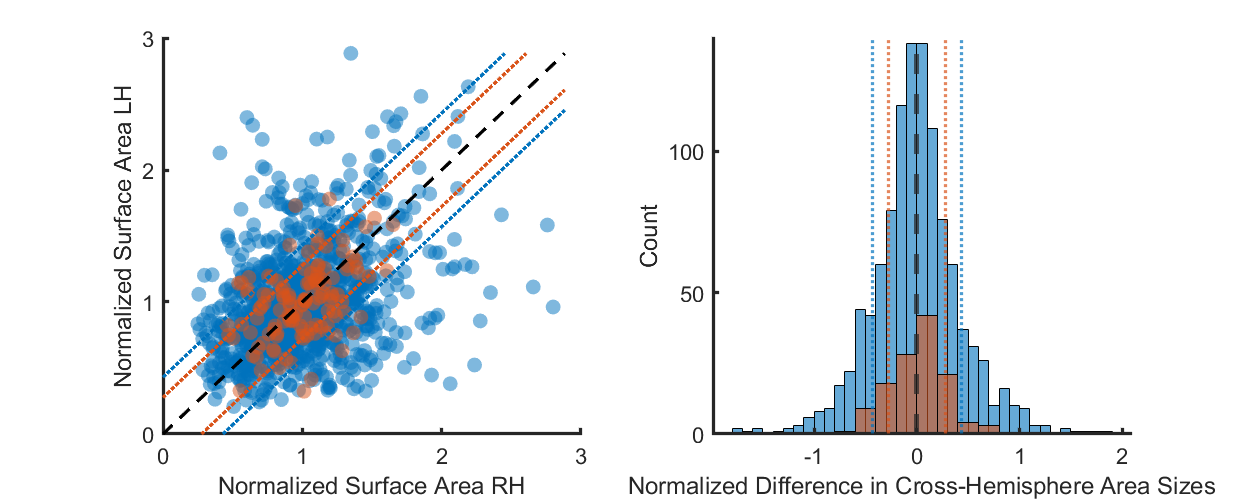


figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1)
s1 = scatter(surfacearea_human_norm{1}(:),surfacearea_human_norm{2}(:),80,'filled');
s1.MarkerFaceAlpha = 0.5;
hold on;
s2 = scatter(surfacearea_monkey_norm{1}(:),surfacearea_monkey_norm{2}(:),80,'filled');
s2.MarkerFaceAlpha = 0.5;
max_value=max([max(surfacearea_human_norm{1}(:)),max(surfacearea_human_norm{2}(:))]);
min_value=floor([min(surfacearea_human_norm{1}(:)),min(surfacearea_human_norm{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
plot([min_value, max_value-humanstd],[min_value+humanstd,max_value],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value+humanstd, max_value],[min_value,max_value-humanstd],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value, max_value-monkstd],[min_value+monkstd,max_value],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot([min_value+monkstd, max_value],[min_value,max_value-monkstd],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xlabel('Normalized Surface Area RH')
ylabel('Normalized Surface Area LH')
% title(['Two Sample F Test: p = ',num2str(p)])
xticks(0:4)
yticks(0:4)
ax = gca;
ax.XAxis.LineWidth = 2;
ax.YAxis.LineWidth = 2;
ax.FontSize = 13;

subplot(1,2,2)
% figure('Renderer', 'painters', 'Position', [10 10 600 500]);
histogram((surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:)));
hold on;
histogram((surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:)));
xline(0,'--','linewidth',3)
xline(humanstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(-humanstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(monkstd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xline(-monkstd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
box off
xlabel('Normalized Difference in Cross-Hemisphere Area Sizes')
ylabel('Count')
% legend('Humans','Monkeys')
% title(['Two Sample F Test: p = ',num2str(p)])
xticks(-2:2)
yticks(0:50:200)
ax = gca;
ax.XAxis.LineWidth = 2;
ax.YAxis.LineWidth = 2;
ax.FontSize = 13;

## Supp Fig 5

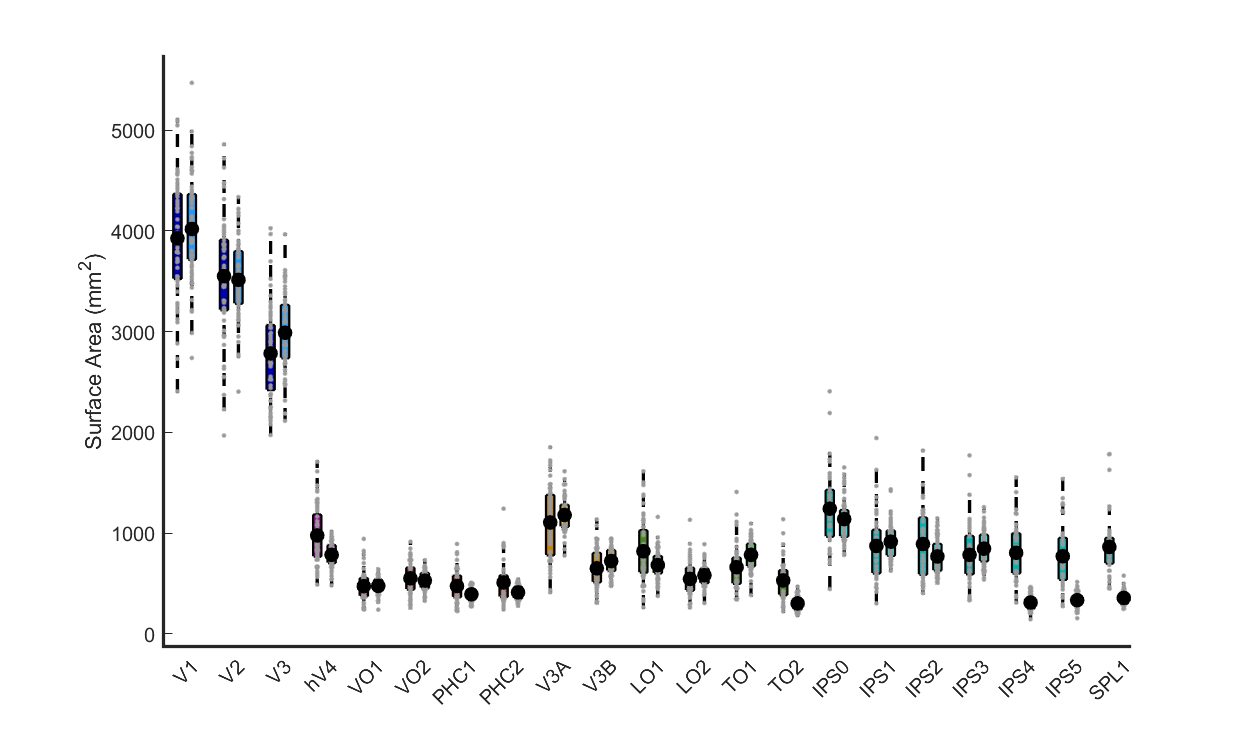

surfacearea_total_prob = human_data.total_size_prob;

% get average of white matter and pial surface area
human_surfacearea_avg_prob = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm_prob, human_data.surfacearea_pial_prob,'UniformOutput',false);

human_bothhemi_SA_prob = [human_surfacearea_avg_prob{1} + human_surfacearea_avg_prob{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(1:2,:),1);
V2_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(3:4,:),1);
V3_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(5:6,:),1);

SA_sumvd_human_prob = [V1_sumhemis_sumvd_prob;V2_sumhemis_sumvd_prob;...
    V3_sumhemis_sumvd_prob;human_bothhemi_SA_prob(7:end,:)];

human_bothhemi_SA_prob = [human_surfacearea_avg_prob{1} human_surfacearea_avg_prob{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(1:2,:),1);
V2_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(3:4,:),1);
V3_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(5:6,:),1);

SA_catvd_human_prob = [V1_sumhemis_sumvd_prob;V2_sumhemis_sumvd_prob;...
    V3_sumhemis_sumvd_prob;human_bothhemi_SA_prob(7:end,:)];

total_catvd_human_prob = [surfacearea_total_prob(:,1);surfacearea_total_prob(:,2)];

EVCrois_human=1:6; EVCcolor=[0.1 0.6 1];
V4rois_human=7; V4color=[1 0.2 1];
ventralrois_human=8:11; ventralcolor=[1 0.2 0.2];
dorsalrois_human=12:13; dorsalcolor=[1 .8 0];
lateralrois_human=15:18; lateralcolor=[0 1 0];
parietalrois_human=19:25; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
allrois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human};
alllabels_human = human_data.labels;
use_colorscale_indiv_all=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1)];

evccolor=[0 0 0.7];
v4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0];
lateralcolor=[0.2784    0.5216    0.1451];
parietalcolor=[0 0.7 0.7];
use_colorscale_prob_all=[repmat(evccolor,length(EVCrois_human),1);...
    repmat(v4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1)];

alllabs = cat(2,{'V1','V2','V3'},alllabels_human(7:end));

use_colorscale_inv_indiv=flipud(use_colorscale_indiv_all);
use_colorscale_inv_prob=flipud(use_colorscale_prob_all);


% pad array with nan to get the same size as humans
concat_data = [];
concat_colorscale = [];
for i = 1:size(sum_human,1)
    concat_data = [concat_data; sum_human(i,:); SA_sumvd_human_prob(i,:)];
    concat_colorscale = [concat_colorscale;use_colorscale_inv_indiv(i,:);use_colorscale_inv_prob(i,:)];
end

% set groupings by species and areas to use factorgap in boxplot
g1 = sort([1:size(sum_human,1),1:size(sum_human,1)]);
g2 = repmat(1:2,[1,size(sum_human,1)]);

figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
hold on
h1=boxplot(concat_data',[g1' g2'],'factorgap',3,'colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(concat_data,1)
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   patch(get(h1(j),'XData'),get(h1(j),'YData'),concat_colorscale(j,:),'FaceAlpha',1);
end

plotSpread(concat_data','xValues',fliplr(xd),'distributionColors',concat_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(fliplr(xd),nanmean(concat_data'),'k.','MarkerSize',30);

% take average of x values for each area to put xticklabel in the middle
xt = [];
for i = 1:length(xd)/2
    xt(i) = (xd(2*i-1) + xd(2*i))/2;
end

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
ax.FontSize = 15;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',fliplr(xt),'xticklabel', alllabs,'fontsize',12);
% xlabel('Visual Areas');
ylabel('Surface Area (mm^2)');

## Supp Fig 6 in paper_figs.mlx

## Supp Fig 7A&D

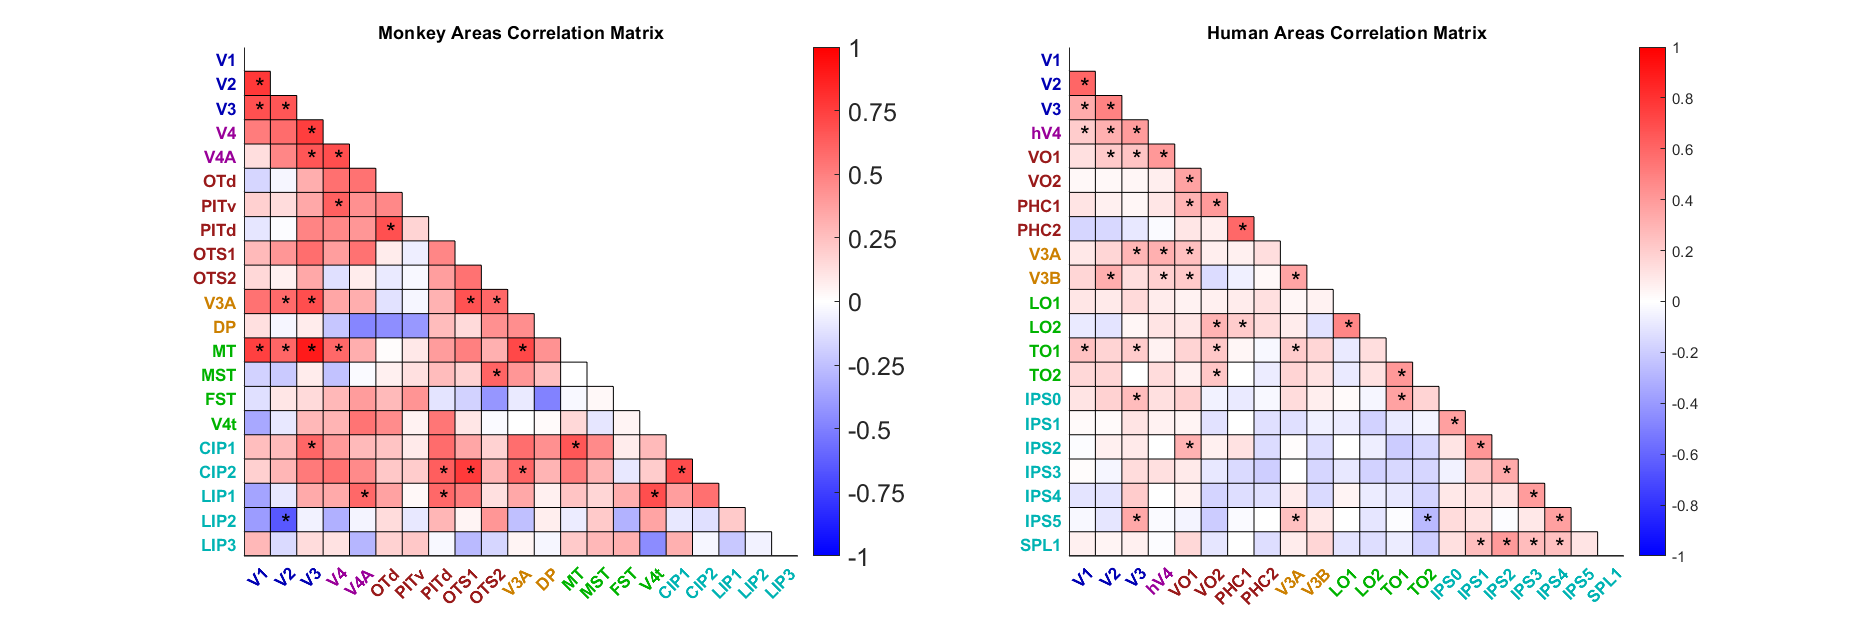

alllabels_monkey = cat(2,{'V1','V2','V3','V4','V4A'},monkey_data.labels(11:end));
alllabels_human = cat(2,{'V1','V2','V3'},human_data.labels(7:end));

all_area_corr_human = zeros(length(alllabels_human),length(alllabels_human));
all_area_pval_human = zeros(length(alllabels_human),length(alllabels_human));
for i = 1:length(alllabels_human)
    for j = 1:length(alllabels_human)
        include = ~isnan(cat_human(i,:)) & ~isnan(cat_human(j,:));
        [r,p] = corr(cat_human(i,include)',cat_human(j,include)');
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_monkey = zeros(length(alllabels_monkey),length(alllabels_monkey));
all_area_pval_monkey = zeros(length(alllabels_monkey),length(alllabels_monkey));
for i = 1:length(alllabels_monkey)
    for j = 1:length(alllabels_monkey)
        include = ~isnan(cat_monkey(i,:)) & ~isnan(cat_monkey(j,:));
        [r,p] = corr(cat_monkey(i,include)',cat_monkey(j,include)');
        all_area_pval_monkey(i,j) = p;
        all_area_corr_monkey(i,j) = r;
    end
end

EVCcolor=[0 0 0.7];
V4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralcolor=[0 0.7 0];
parietalcolor=[0 0.7 0.7];
frontalcolor=[.4 0 .4];

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
subplot(1,2,1);
Z = ones(size(all_area_corr_monkey,1), size(all_area_corr_monkey,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_monkey);
lower_tri(1:length(lower_tri)+1:end) = 0;
alphadata = double(lower_tri ~= 0);
p_tri = tril(all_area_pval_monkey);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;

h2 = imagesc(all_area_corr_monkey);
h2.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_monkey,1)
    for j = 1:size(all_area_corr_monkey,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_monkey)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_monkey)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')    
end

% Xticklabels = get(gca,'XDisplayLabels');
Xticklabels_new = cell(size(alllabels_monkey));
% Yticklabels = get(gca,'YDisplayLabels');
Yticklabels_new = cell(size(alllabels_monkey));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], EVCcolor);
end
for i = 4:5
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], V4color);
end
for i = 6:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], ventralcolor);
end
for i = 11:12
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], dorsalcolor);
end
for i = 13:16
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], lateralcolor);
end
for i = 17:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], parietalcolor);
end
ax = gca;
set(ax, 'XTick',1:length(alllabels_monkey),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_monkey),'YTickLabel',Yticklabels_new)
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];
% set(ax,'xaxisLocation','top')
colormap(redblue);c = colorbar;caxis([-1 1]);c.Ticks = -1:0.25:1;c.FontSize = 15;

title('Monkey Areas Correlation Matrix')

subplot(1,2,2)
Z = ones(size(all_area_corr_human,1), size(all_area_corr_human,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_human);
lower_tri(1:length(lower_tri)+1:end) = 0;
p_tri = tril(all_area_pval_human);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;
alphadata = double(lower_tri ~= 0);

h1 = imagesc(all_area_corr_human);
h1.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_human,1)
    for j = 1:size(all_area_corr_human,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_human)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_human)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')
end
Xticklabels_new = cell(size(alllabels_human));
Yticklabels_new = cell(size(alllabels_human));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], EVCcolor);
end
for i = 4
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], V4color);
end
for i = 5:8
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], ventralcolor);
end
for i = 9:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], dorsalcolor);
end
for i = 11:14
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], lateralcolor);
end
for i = 15:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], parietalcolor);
end

ax = gca;
set(ax, 'XTick',1:length(alllabels_human),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_human),'YTickLabel',Yticklabels_new)
% set(ax,'xaxisLocation','top')
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];

colormap(redblue);c = colorbar;caxis([-1 1]);
title('Human Areas Correlation Matrix')

## Supp Fig 7B&E

monkey_prox_mat = load('./completeData/monkey_prox_mat.mat');
monkey_prox_mat = table2array(monkey_prox_mat.VisualAreaProximityMatrixS1);
monkey_prox_mat(15,13) = 2;
monkey_prox_mat(16,14) = 2;

human_prox_mat = load('./completeData/human_prox_mat.mat');
human_prox_mat = table2array(human_prox_mat.VisualAreaProximityMatrix);

monkey_corr_all = all_area_corr_monkey(:);
monkey_prox_all = monkey_prox_mat(:);

rem_zeros = monkey_prox_all~=0;
monkey_corr_all = monkey_corr_all(rem_zeros);
monkey_prox_all = monkey_prox_all(rem_zeros);

[p,h,stats] = ranksum(monkey_corr_all(monkey_prox_all==1),monkey_corr_all(monkey_prox_all==2))

p = 0.0542

h = logical
   0


stats = struct with fields:
       zval: 1.9256
    ranksum: 799


[p,h,stats] = ranksum(monkey_corr_all(monkey_prox_all==2),monkey_corr_all(monkey_prox_all==3))

p = 0.0820

h = logical
   0


stats = struct with fields:
       zval: 1.7390
    ranksum: 3158


[p,h,stats] = ranksum(monkey_corr_all(monkey_prox_all==1),monkey_corr_all(monkey_prox_all==3))

p = 8.5392e-05

h = logical
   1


stats = struct with fields:
       zval: 3.9287
    ranksum: 3231



figure(); 
subplot(1,2,1);hold on;
viol1 = violinplot(monkey_corr_all,monkey_prox_all,'ViolinColor',monkey_orange,'MedianMarkerSize',100);
yline(0,'k--')
ylim([-1 1])
yticks(-1:0.5:1)
box off;

human_corr_all = all_area_corr_human(:);
human_prox_all = human_prox_mat(:);

rem_zeros = human_prox_all~=0;
human_corr_all = human_corr_all(rem_zeros);
human_prox_all = human_prox_all(rem_zeros);

[p,h,stats] = ranksum(human_corr_all(human_prox_all==1),human_corr_all(human_prox_all==2))

p = 6.4314e-06

h = logical
   1


stats = struct with fields:
       zval: 4.5117
    ranksum: 957


[p,h,stats] = ranksum(human_corr_all(human_prox_all==2),human_corr_all(human_prox_all==3))

p = 0.0017

h = logical
   1


stats = struct with fields:
       zval: 3.1376
    ranksum: 3862


[p,h,stats] = ranksum(human_corr_all(human_prox_all==1),human_corr_all(human_prox_all==3))

p = 7.1129e-11

h = logical
   1


stats = struct with fields:
       zval: 6.5183
    ranksum: 3679


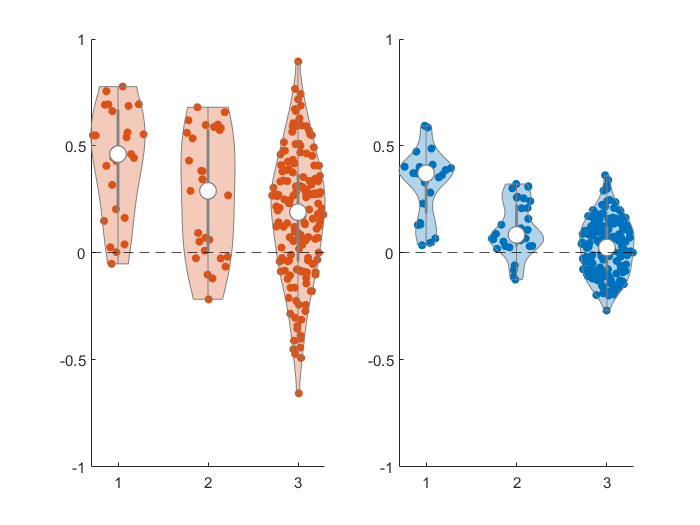


subplot(1,2,2); hold on;
viol1 = violinplot(human_corr_all,human_prox_all,'ViolinColor',human_blue,'MedianMarkerSize',100);
yline(0,'k--')
ylim([-1 1])
yticks(-1:0.5:1)
box off;

## Supp Fig 7C&F

human_cluster_mat = load('./completeData/human_cluster_mat.mat');human_cluster_mat = human_cluster_mat.VisualAreaProximityMatrixS1;
human_cluster_mat(end-3:end,end-3:end) = nan;
monkey_cluster_mat = load('./completeData/monkey_cluster_mat.mat');monkey_cluster_mat = monkey_cluster_mat.VisualAreaProximityMatrixS3;
monkey_cluster_mat(end,end) = nan;

corr_human = tril(all_area_corr_human);
corr_human(1:length(corr_human)+1:end) = 0;

corr_monkey = tril(all_area_corr_monkey);
corr_monkey(1:length(corr_monkey)+1:end) = 0;

human_within = all_area_corr_human(human_cluster_mat==1 & human_prox_mat==1);
human_between = all_area_corr_human(human_cluster_mat==0 & human_prox_mat==1);

monkey_within = all_area_corr_monkey(monkey_cluster_mat==1 & monkey_prox_mat==1);
monkey_between = all_area_corr_monkey(monkey_cluster_mat==0 & monkey_prox_mat==1);

[p,h,stats] = ranksum(human_within,human_between)

p = 0.0356

h = logical
   1


stats = struct with fields:
       zval: 2.1013
    ranksum: 159


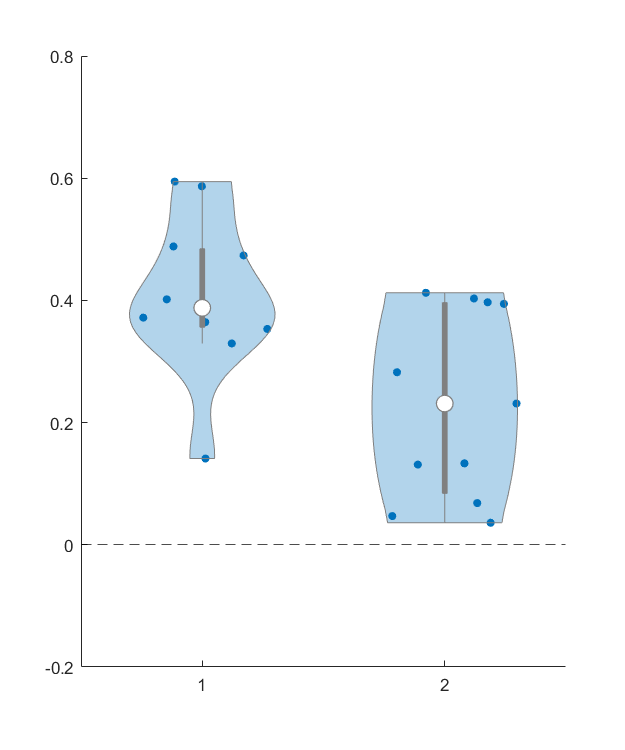


figure('Renderer', 'painters', 'Position', [10 10 500 600]); hold on;
viol1 = violinplot([human_within; human_between],[ones(length(human_within),1);ones(length(human_between),1)*2],'ViolinColor',human_blue,'MedianMarkerSize',100);
yline(0,'k--')
ylim([-0.2 0.8])
yticks(-0.2:0.2:0.8)
box off;


[p,h,stats] = ranksum(monkey_within,monkey_between)

p = 0.8461

h = logical
   0


stats = struct with fields:
       zval: 0.1941
    ranksum: 199


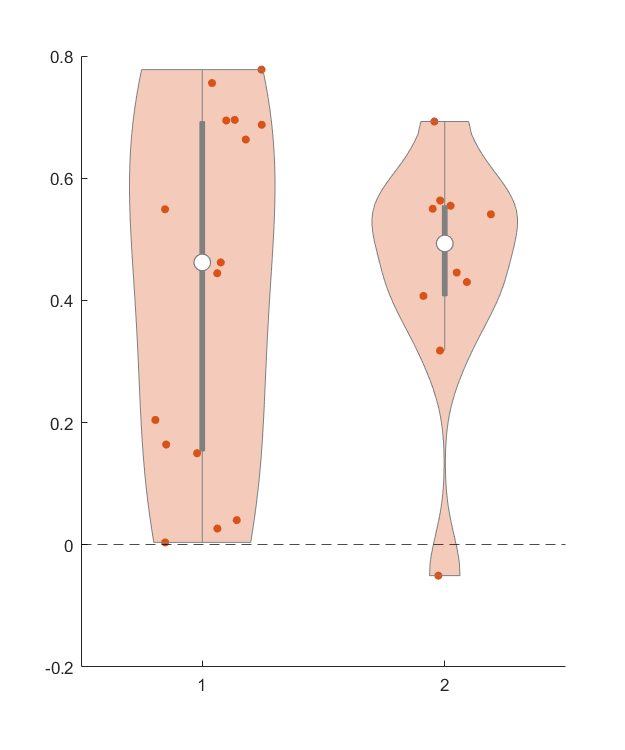


figure('Renderer', 'painters', 'Position', [10 10 500 600]); hold on;
viol1 = violinplot([monkey_within; monkey_between],[ones(length(monkey_within),1);ones(length(monkey_between),1)*2],'ViolinColor',monkey_orange,'MedianMarkerSize',100);
% viol1 = violinplot([monkey_within([1:9,14:15]); monkey_between],[ones(length(monkey_within)-4,1);ones(length(monkey_between),1)*2],'ViolinColor',monkey_orange,'MedianMarkerSize',100);
yline(0,'k--')
ylim([-0.2 0.8])
yticks(-0.2:0.2:0.8)
box off;


for i = 1:3
    p = ranksum(human_corr_all(human_prox_all==i),monkey_corr_all(monkey_prox_all==i))
end

p = 0.0385

p = 0.0410

p = 5.0334e-08

## Supp Table 1&2

% Human values
alllabels_human_merge = {'V1','V2','V3','V4','VO1','VO2','PHC1','PHC2','V3A','V3B','LO1','LO2','TO1','TO2','IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};
array_labels = {'Mean +/- St Dev','Min','Max','V1 Norm Mean +/- St Dev','Norm Min','Norm Max','Cross-Hemi Corr'};

concat_bothhemi_human = surfacearea_human{1} + surfacearea_human{2};
surfacearea_human_merge = nan(length(alllabels_human_merge),size(concat_bothhemi_human,2));
surfacearea_human_merge(1,:) = concat_bothhemi_human(1,:)+concat_bothhemi_human(2,:);
surfacearea_human_merge(2,:) = concat_bothhemi_human(3,:)+concat_bothhemi_human(4,:);
surfacearea_human_merge(3,:) = concat_bothhemi_human(5,:)+concat_bothhemi_human(6,:);
surfacearea_human_merge(4:end,:) = concat_bothhemi_human(7:end,:);

xhemi_corr_human = [];
xhemi_corr_monkey = [];
for i = 1:size(surfacearea_human_merge,1)
    include = find(~isnan(cat_human(i,1:62)) & ~isnan(cat_human(i,63:end)));
    xhemi_corr_human(i) = round(corr(cat_human(i,include)',cat_human(i,include+62)'),2);
    
    include = find(~isnan(cat_monkey(i,1:6)) & ~isnan(cat_monkey(i,7:end)));
    xhemi_corr_monkey(i) = corr(cat_monkey(i,include)',cat_monkey(i,include+6)');
end

surfacearea_human_merge_norm = surfacearea_human_merge./surfacearea_human_merge(1,:);

array_of_values_human = nan(size(surfacearea_human_merge,1),8);
array_of_values_human(:,1) = mean(surfacearea_human_merge,2,'omitnan');
array_of_values_human(:,2) = std(surfacearea_human_merge,[],2,'omitnan')/sqrt(size(surfacearea_human_merge,2));
array_of_values_human(:,3) = min(surfacearea_human_merge,[],2,'omitnan');
array_of_values_human(:,4) = max(surfacearea_human_merge,[],2,'omitnan');

array_of_values_human(:,5) = mean(surfacearea_human_merge_norm,2,'omitnan');
array_of_values_human(:,6) = std(surfacearea_human_merge_norm,[],2,'omitnan')/sqrt(size(surfacearea_human_merge_norm,2));
array_of_values_human(:,7) = min(surfacearea_human_merge_norm,[],2,'omitnan');
array_of_values_human(:,8) = max(surfacearea_human_merge_norm,[],2,'omitnan');
array_of_values_human(:,1:4) = round(array_of_values_human(:,1:4),2);
array_of_values_human(:,5:8) = round(array_of_values_human(:,5:8),4);

s1 = {};
s2 = {};
s3 = {};
s4 = {};
for i = 1:size(array_of_values_human,1)
    s1{i} = strcat(num2str(round(array_of_values_human(i,1),3,'significant')),' +/- ',num2str(round(array_of_values_human(i,2),3,'significant')));
    s2{i} = strcat(num2str(round(array_of_values_human(i,3),3,'significant')),' - ',num2str(round(array_of_values_human(i,4),3,'significant')));
    s3{i} = strcat(num2str(round(array_of_values_human(i,5),3,'significant')),' +/- ',num2str(round(array_of_values_human(i,6),3,'significant')));
    s4{i} = strcat(num2str(round(array_of_values_human(i,7),3,'significant')),' - ',num2str(round(array_of_values_human(i,8),3,'significant')));
end

full_table_human = table(s1',s2',s3',s4',round(xhemi_corr_human,2,'significant')','VariableNames',{'Mean +/- SE','Min - Max','Norm Mean +/- SE','Norm Min - Max','Cross-Hemi Corr'},'RowNames',alllabels_human_merge);

% table_of_values_human = array2table(round(array_of_values_human,3,'significant'),'VariableNames',array_labels,'RowNames',alllabels_human_merge);
% writetable(full_table_human,'human_table.xls')

% Monkey values
alllabels_monkey_merge = {'V1','V2','V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};

concat_bothhemi_monkey = surfacearea_monkey{1} + surfacearea_monkey{2};
surfacearea_monkey_merge = nan(length(alllabels_monkey_merge),size(concat_bothhemi_monkey,2));
surfacearea_monkey_merge(1,:) = concat_bothhemi_monkey(1,:)+concat_bothhemi_monkey(2,:);
surfacearea_monkey_merge(2,:) = concat_bothhemi_monkey(3,:)+concat_bothhemi_monkey(4,:);
surfacearea_monkey_merge(3,:) = concat_bothhemi_monkey(5,:)+concat_bothhemi_monkey(6,:);
surfacearea_monkey_merge(4,:) = concat_bothhemi_monkey(7,:)+concat_bothhemi_monkey(8,:);
surfacearea_monkey_merge(5,:) = concat_bothhemi_monkey(9,:)+concat_bothhemi_monkey(10,:);
surfacearea_monkey_merge(6:end,:) = concat_bothhemi_monkey(11:end,:);

surfacearea_monkey_merge_norm = surfacearea_monkey_merge./surfacearea_monkey_merge(1,:);

array_of_values_monkey = nan(size(surfacearea_monkey_merge,1),8);
array_of_values_monkey(:,1) = mean(surfacearea_monkey_merge,2,'omitnan');
array_of_values_monkey(:,2) = std(surfacearea_monkey_merge,[],2,'omitnan')/sqrt(size(surfacearea_monkey_merge,2));
array_of_values_monkey(:,3) = min(surfacearea_monkey_merge,[],2,'omitnan');
array_of_values_monkey(:,4) = max(surfacearea_monkey_merge,[],2,'omitnan');

array_of_values_monkey(:,5) = mean(surfacearea_monkey_merge_norm,2,'omitnan');
array_of_values_monkey(:,6) = std(surfacearea_monkey_merge_norm,[],2,'omitnan')/sqrt(size(surfacearea_monkey_merge_norm,2));
array_of_values_monkey(:,7) = min(surfacearea_monkey_merge_norm,[],2,'omitnan');
array_of_values_monkey(:,8) = max(surfacearea_monkey_merge_norm,[],2,'omitnan');
array_of_values_monkey(:,1:4) = round(array_of_values_monkey(:,1:4),2);
array_of_values_monkey(:,5:8) = round(array_of_values_monkey(:,5:8),4);

s1 = {};
s2 = {};
s3 = {};
s4 = {};
for i = 1:size(array_of_values_monkey,1)
    s1{i} = strcat(num2str(round(array_of_values_monkey(i,1),3,'significant')),' +/- ',num2str(round(array_of_values_monkey(i,2),3,'significant')));
    s2{i} = strcat(num2str(round(array_of_values_monkey(i,3),3,'significant')),' - ',num2str(round(array_of_values_monkey(i,4),3,'significant')));
    s3{i} = strcat(num2str(round(array_of_values_monkey(i,5),3,'significant')),' +/- ',num2str(round(array_of_values_monkey(i,6),3,'significant')));
    s4{i} = strcat(num2str(round(array_of_values_monkey(i,7),3,'significant')),' - ',num2str(round(array_of_values_monkey(i,8),3,'significant')));
end

full_table_monkey = table(s1',s2',s3',s4',round(xhemi_corr_human,2,'significant')','VariableNames',{'Mean +/- SE','Min - Max','Norm Mean +/- SE','Norm Min - Max','Cross-Hemi Corr'},'RowNames',alllabels_monkey_merge);

% table_of_values_monkey = array2table(round(array_of_values_monkey,3,'significant'),'VariableNames',array_labels,'RowNames',alllabels_monkey_merge);
% writetable(full_table_monkey,'monk_table.xls')